When this circuit:

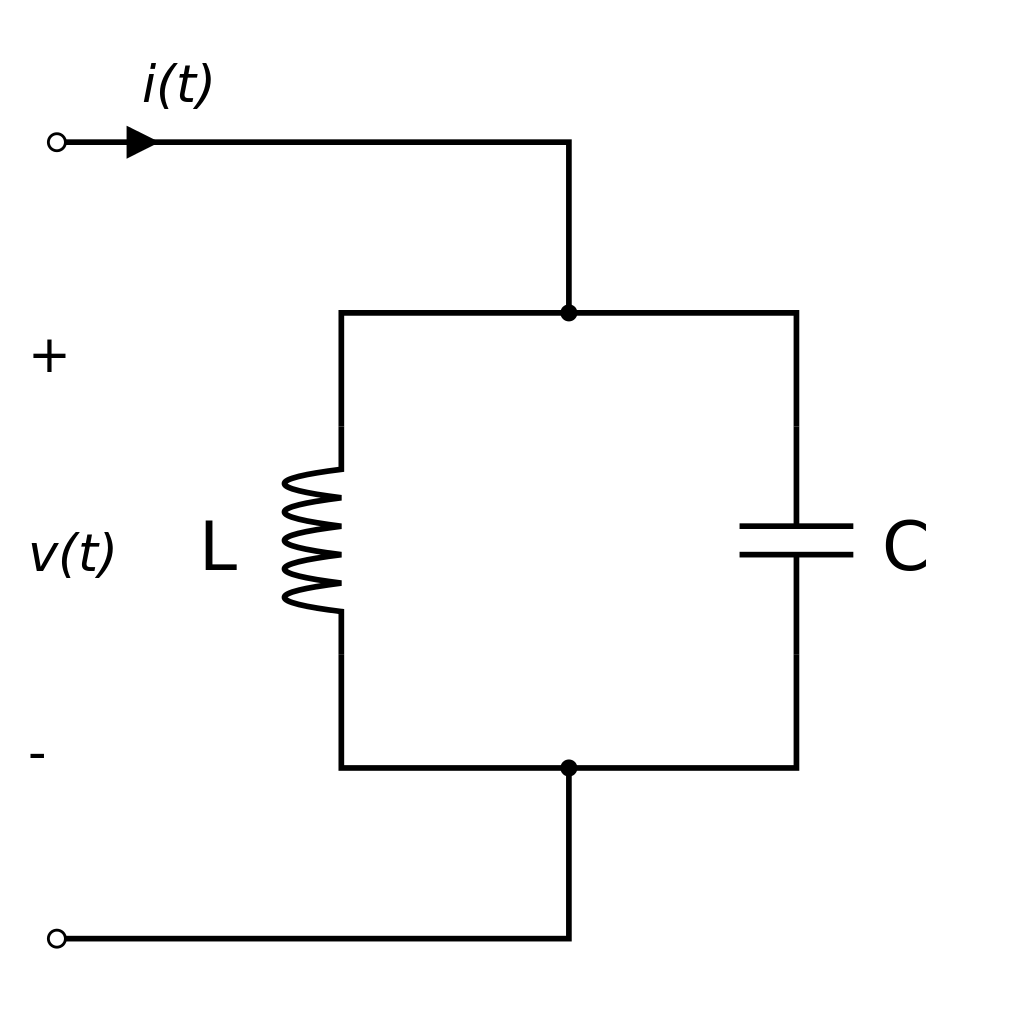

is powered directly by an AC voltage source, we need to model it as such:

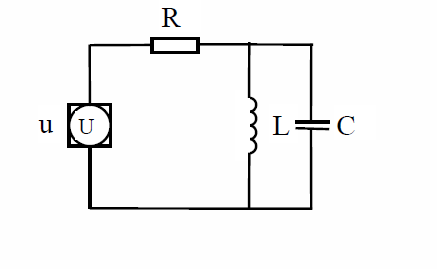

With R being a very small internal resistance to the voltage source.  Otherwise, we will not be able to determine the source current.  

We could compute the total impedance and divide the source to get the answer, but this may not be entirely c

clear all
close all
clc

syms t

Rs = 1e-8;
L = 1e-1;
C = 1e-3;
f = 60

f = 60

Vs(t) = 120*sin(2*pi*f*t)

$$Vs(t) = 120\,\sin\left(120\,\pi \,t\right)$$


syms IL(t)
dIL(t) = diff(IL);
ddIL(t) = diff(dIL);

ode_il = Rs*C*L*ddIL + (Rs/L)*IL + L*dIL == Vs;
ics = [IL(0) == 0, dIL(0) == 0]

$$ics = \left(\begin{array}{cc} \mathrm{IL}\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}\mathrm{IL}\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

IL_sol = dsolve(ode_il, ics);
simplify(IL_sol);
dVs(t) = diff(Vs);

syms IC(t)
dIC(t) = diff(IC);
ddIC(t) = diff(dIC);
ode_ic = Rs*ddIC + (Rs/L*C)*IC + (1/C)*dIC == diff(Vs,2);
ics = [IC(0) == Vs(0)/Rs, dIC(0) == dVs(0)/Rs]

$$ics = \left(\begin{array}{cc} \mathrm{IC}\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}\mathrm{IC}\left(t\right)\right)|}_{t=0}\right)=1440000000000\,\pi \end{array}\right)$$

IC_sol = dsolve(ode_ic, ics);

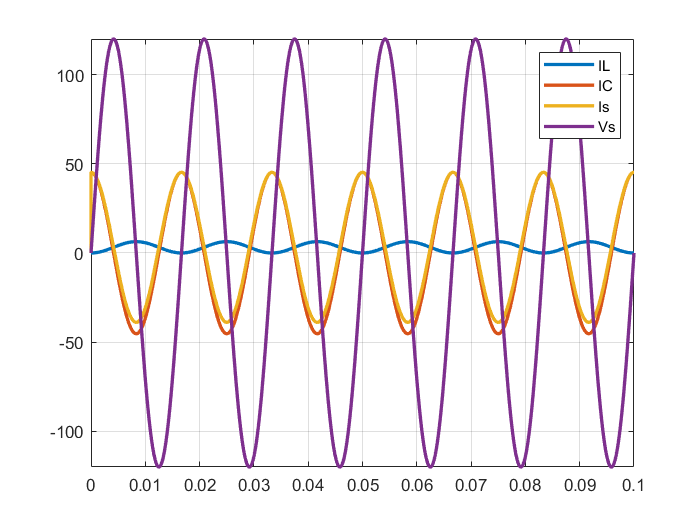

fplot(IL_sol,'LineWidth',2)
xlim([0 0.1])
grid on
hold on
fplot(IC_sol,'LineWidth',2)
fplot(IL_sol + IC_sol,'LineWidth',2)
fplot(Vs,'LineWidth',2)
legend("IL", "IC", "Is", "Vs")
hold off

We see Is jumps up suddenly.  The next section shows this is due to the capacitor charging.

fplot(IL_sol + IC_sol)
hold on
fplot(Vs)
grid on
tau = Rs*C

tau = 1.0000e-11

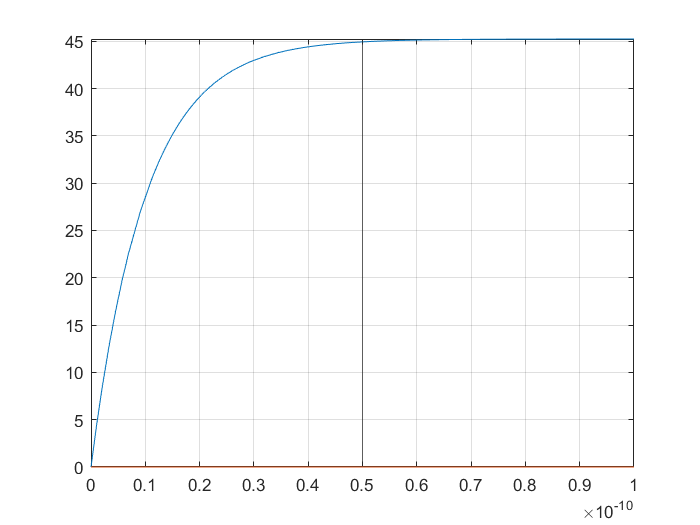

xlim([0 10*tau])
xline(5*tau);
hold off